# Inputs

T = 1200; % Sample time
Ts = 10; % Points number

Pmax = 1500;
Pmid = 1250;
Pcruise = 1000;

# Power profile (Noise)

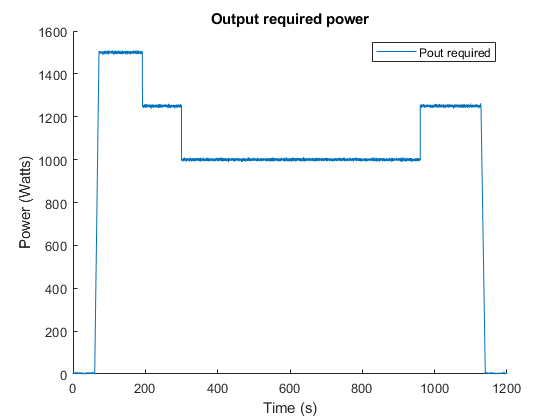

T1 = 5/100*T;
T2 = 1/100*T;
T3 = 10/100*T;
T4 = 9/100*T;
T5 = 55/100*T;
T6 = 14/100*T;
T7 = 1/100*T;
T8 = 5/100*T;

F1 = linspace(0,0,T1*Ts);
F2 = linspace(0,1500,T2*Ts);
F3 = linspace(1500,1500,T3*Ts);
F4 = linspace(1250,1250,T4*Ts);
F5 = linspace(1000,1000,T5*Ts);
F6 = linspace(1250,1250,T6*Ts);
F7 = linspace(1250,0,T7*Ts);
F8 = linspace(0,0,T8*Ts);

x = [F1 F2 F3 F4 F5 F6 F7 F8];
w = awgn(x,50,'measured');

t = linspace(0,T,T*Ts);

clf;
% plot(t,x)
hold on;
plot(t,w)
legend('Pout required');
title('Output required power');
ylabel('Power (Watts)');
xlabel('Time (s)');
ylim([0 1600]);

# Flight scheme

% T1 = 5/100;
% T2 = 15/100;
% T3 = 60/100;
% T4 = T2;
% T5 = T1;
% 
% F1 = linspace(0,0,T1*Ts);
% F2 = linspace(0,1500,T2*Ts);
% F3 = linspace(1500,1500,T3*Ts);
% F4 = linspace(1500,0,T4*Ts);
% F5 = linspace(0,0,T5*Ts);
% 
% x = [F1 F2 F3 F4 F5];
% w = awgn(x,50,'measured');
% 
% t = linspace(0,T,Ts);
% 
% clf;
% plot(t,x)
% hold on;
% % plot(t,w)


New scheme with noise

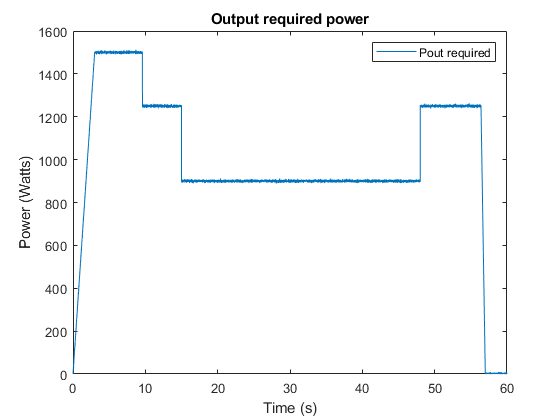

T1 = 5/100*T;
T2 = 1/100*T;
T3 = 10/100*T;
T4 = 9/100*T;
T5 = 55/100*T;
T6 = 14/100*T;
T7 = 1/100*T;
T8 = 5/100*T;

% % take off + climb
% F1 = linspace(0,100,T1*Ts);
% F2 = linspace(100,1500,T2*Ts);
% a = [F1 F2];

% take off + climb
F1 = linspace(0,1500,T1*Ts);
F2 = linspace(1500,1500,T2*Ts);
a = [F1 F2];

% max power + cruise
F3 = linspace(1500,1500,T3*Ts);
F4 = linspace(1250,1250,T4*Ts);
F5 = linspace(900,900,T5*Ts);
b = [F3 F4 F5];

% descend + landing
F6 = linspace(1250,1250,T6*Ts);
F7 = linspace(1250,0,T7*Ts);
F8 = linspace(0,0,T8*Ts);
c = [F6 F7 F8];

% T1 = 5/100;
% T2 = 1/100;
% T3 = 10/100;
% T4 = 9/100;
% T5 = 55/100;
% T6 = 14/100;
% T7 = 1/100;
% T8 = 5/100;
% 
% % take off + climb
% F1 = linspace(0,100,T1*T*T1*Ts);
% F2 = linspace(100,1500,T2*T*T2*Ts);
% a = [F1 F2];
% 
% % max power + cruise
% F3 = linspace(1500,1500,T3*T*T3*Ts);
% F4 = linspace(1250,1250,T4*T*T4*Ts);
% F5 = linspace(1000,1000,T5*T*T5*Ts);
% b = [F3 F4 F5];
% 
% % descend + landing
% F6 = linspace(1250,1250,T6*T*T6*Ts);
% F7 = linspace(1250,0,T7*T*T7*Ts);
% F8 = linspace(0,0,T8*T*T8*Ts);
% c = [F6 F7 F8];

clf;
one_c = [a b c];
% one cycle = ?
t_one_c = linspace(0,60,length(one_c));
one_c_bis = awgn(one_c,50,'measured');
plot(t_one_c,one_c_bis);
legend('Pout required');
title('Output required power');
ylabel('Power (Watts)');
xlabel('Time (s)');
ylim([0 1600]);

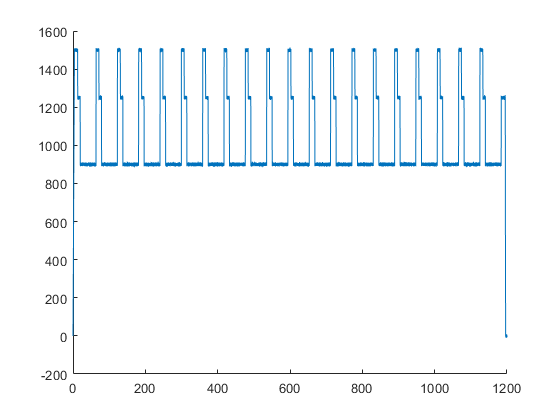



cycle = 20;
temp = [a b];
for i=1:cycle-1
    temp = [temp b];
end
temp = [temp c];
w = awgn(temp,50,'measured');



t = linspace(0,T,length(w));

clf;
% plot(t,x)
hold on;
plot(t,w)


% save(strcat(fileparts(pwd),'\data.mat'),'one_c','t_one_c','w','t')